# Allpass System Lecture


$$G(s) = \frac{1 - as}{1 + as}$$


s = tf('s'); a = 1/5;
G = (1 - a*s)/(1 + a*s)

G =
 
  -0.2 s + 1
  ----------
  0.2 s + 1
 
Continuous-time transfer function.



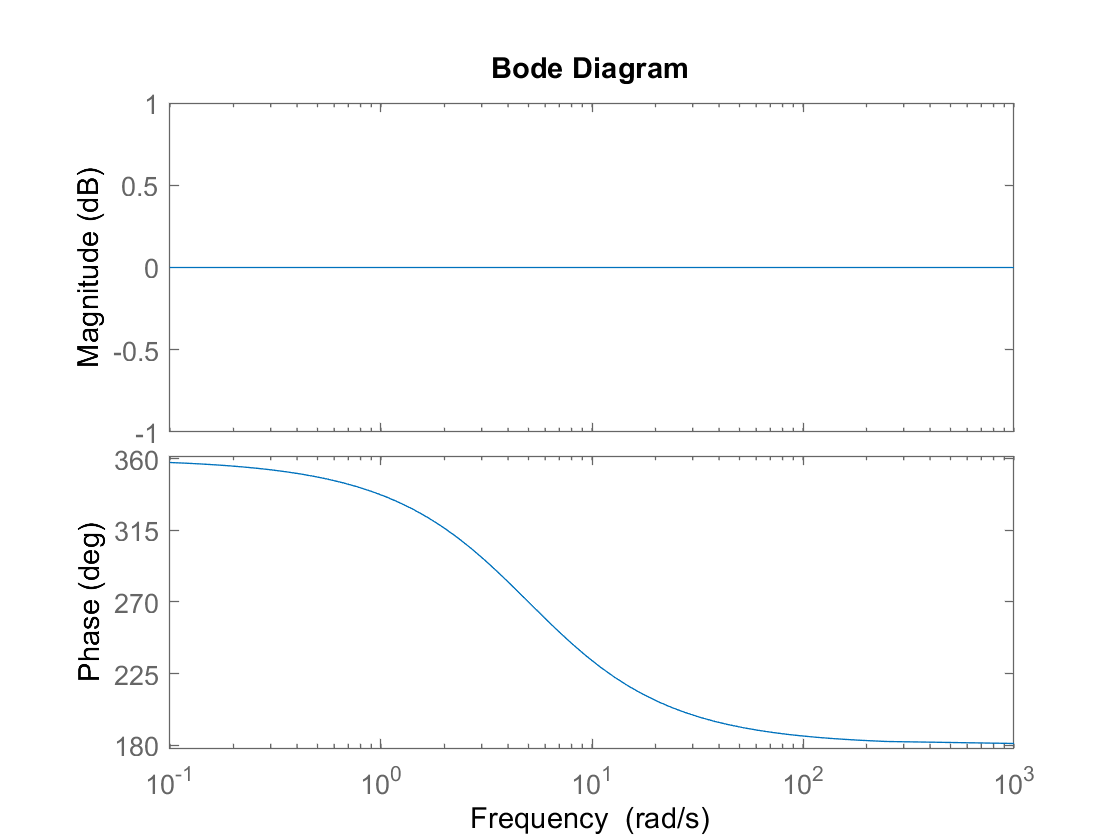

figure, bode(G)

P = 1/(s + 1)

P =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.



k = 1; C = k;
Y = P*G*k 

Y =
 
      -0.2 s + 1
  -------------------
  0.2 s^2 + 1.2 s + 1
 
Continuous-time transfer function.



G = (-k/(s+1))*(s-1/a)/(s+1/a)

G =
 
     -s + 5
  -------------
  s^2 + 6 s + 5
 
Continuous-time transfer function.



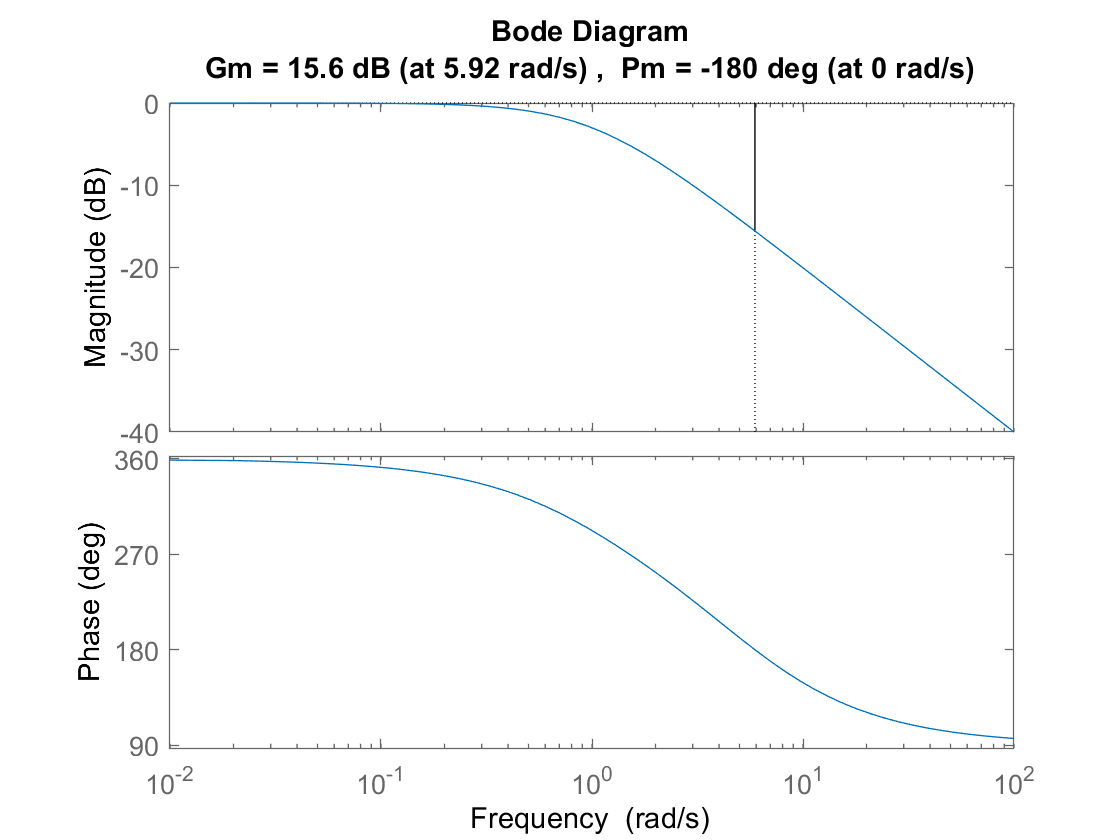

figure, bode(G), margin(G)

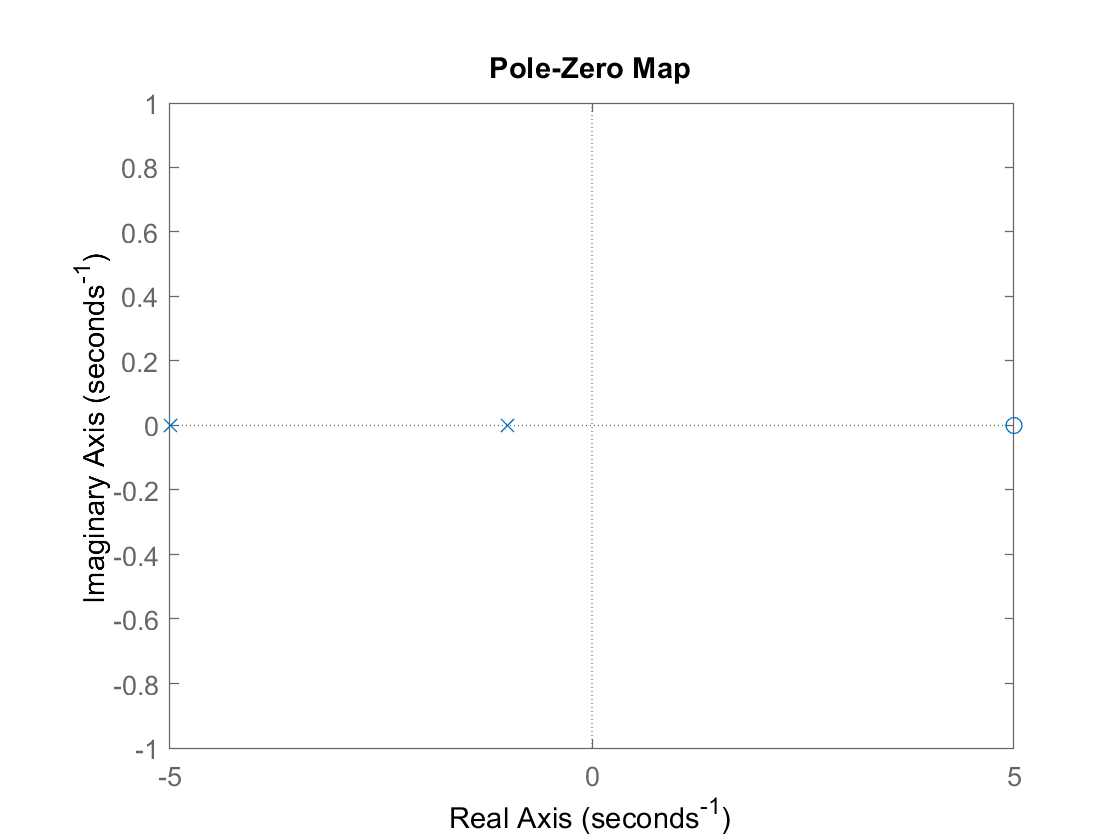

pzmap(G)

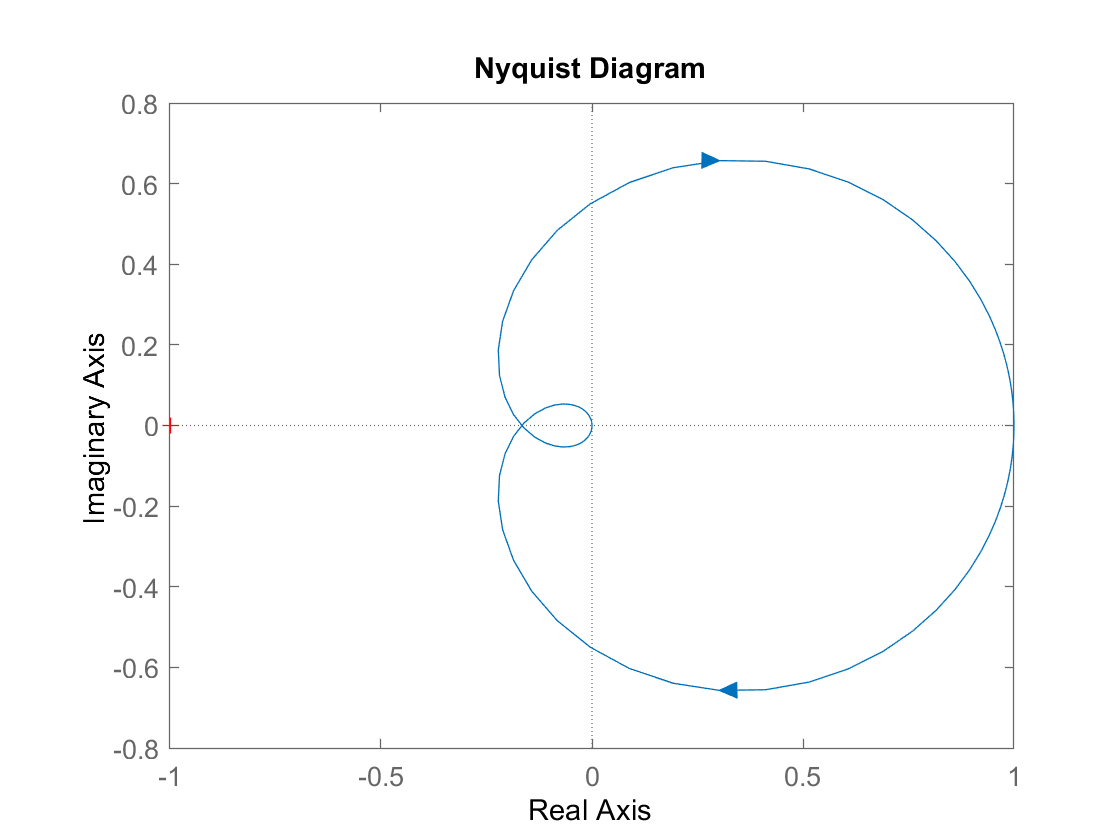

nyquist(G)

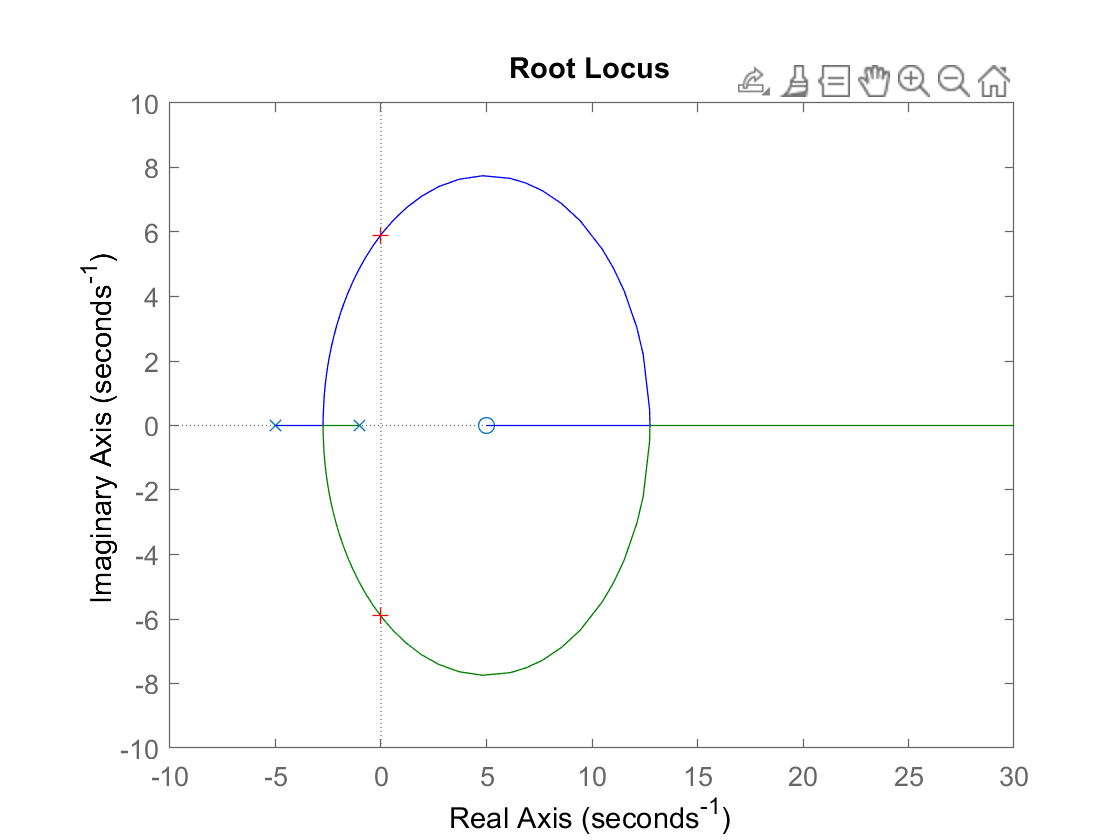

Select a point in the graphics window


selected_point = 0.0237 + 5.8605i

k = 5.9730

poles =   -0.0135 + 5.9046i
  -0.0135 - 5.9046i


rlocus(G)
[k,poles] = rlocfind(G)

Thus, k is about 6 so our range can only be within 


$$0<k<6$$
